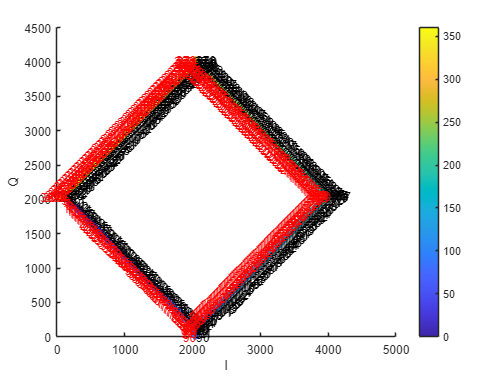

clc
clear all
close all

f_samp = 60.94e6; % do 65 Msps
bit_samp = 12; % 12 bit ADC

f_ref = 10e6; % 10 MHz signal
five_periods = 5/f_ref;

test_gain = 1/10; % 10 dB dampening

% simulation with 100 samples per period
%f_sim = f_samp;
f_sim = 160*f_samp;

% minimum sample size
%mss_mult = 0; % additional bits
%min_mem_size = f_ref/1e6 * f_samp/1e6;%lcm(f_ref/1e6, f_samp/1e6);
%mem_size_n = ceil(log2(min_mem_size)) + mss_mult;
%mem_size = 2^mem_size_n;
mem_size = 4096;
min_sample_time = mem_size/f_samp;

% Generate signals for processing
%out = sim("dataflow.slx");
out.ref = int16( ( sin(2*pi*f_ref*(0:1/f_samp:(mem_size-1)/f_samp))/2 + 0.5 )*2^bit_samp );

%sin_synth = sin(linspace(0, 2*pi, mem_size));
%cos_synth = cos(linspace(0, 2*pi, mem_size));

% FPGA section
sin_synth = int16( ( sin(2*pi*f_ref*(0:1/f_samp:(mem_size-1)/f_samp))/2 + 0.5 )*2^bit_samp );
cos_synth = int16( ( cos(2*pi*f_ref*(0:1/f_samp:(mem_size-1)/f_samp))/2 + 0.5 )*2^bit_samp );
sinsat_synth = bitget(sin_synth, bit_samp);
cossat_synth = bitget(cos_synth, bit_samp);
%sin_synth = sin(2*pi*f_ref*(0:1/f_samp:mem_size/f_samp));
%cos_synth = cos(2*pi*f_ref*(0:1/f_samp:mem_size/f_samp));
%sinsat_synth = sin_synth >= 0;
%cossat_synth = cos_synth >= 0;

test_phase_deg = (0:1:359); % phase shift array
test_phase = test_phase_deg/180*pi; % phase shift array

ref_i_ac = zeros(size(test_phase), "like", test_phase);
ref_q_ac = zeros(size(test_phase), "like", test_phase);

test_i_ac = zeros(size(test_phase), "like", test_phase);
test_q_ac = zeros(size(test_phase), "like", test_phase);

ph_ref_s = zeros(size(test_phase), "like", test_phase);
ph_test_s = zeros(size(test_phase), "like", test_phase);
ph_ref_c = zeros(size(test_phase), "like", test_phase);
ph_test_c = zeros(size(test_phase), "like", test_phase);

for phase_i = 1:size(test_phase,2)
    % test vector
    out.test = int16( ( sin(2*pi*f_ref*(0:1/f_samp:(mem_size-1)/f_samp) + test_phase(phase_i))/2 + 0.5 )*2^bit_samp );
    
    for n = 1:mem_size
        % Take the samples
        ref_s = out.ref(n);
        test_s = out.test(n);
    
        % Get MSB (effectively saturating the signal)
        ref_sig = bitget(ref_s, bit_samp);
        test_sig = bitget(test_s, bit_samp);
        
        % Mix the signals
        ref_imix = xor(ref_sig, sinsat_synth(n));
        ref_qmix = xor(ref_sig, cossat_synth(n));
        test_imix = xor(test_sig, sinsat_synth(n));
        test_qmix = xor(test_sig, cossat_synth(n));
        
        % accumulate values
        ref_i_ac(phase_i) = ref_i_ac(phase_i) + ref_imix;
        ref_q_ac(phase_i) = ref_q_ac(phase_i) + ref_qmix;
    
        test_i_ac(phase_i) = test_i_ac(phase_i) + test_imix;
        test_q_ac(phase_i) = test_q_ac(phase_i) + test_qmix;
    end
    
    % vsakih mem_size ciklov se izvede izračun končnih vrednosti
    if ref_q_ac(phase_i) < mem_size/2
        ph_ref_s(phase_i) = 180*ref_i_ac(phase_i)/mem_size;
    else
        ph_ref_s(phase_i) = -180*ref_i_ac(phase_i)/mem_size;
    end

    if test_q_ac(phase_i) < mem_size/2
        ph_test_s(phase_i) = 180*test_i_ac(phase_i)/mem_size;
    else
        ph_test_s(phase_i) = -180*test_i_ac(phase_i)/mem_size;
    end

    if ref_i_ac(phase_i) < mem_size/2
        ph_ref_c(phase_i) = 90-180*ref_q_ac(phase_i)/mem_size;
    else
        ph_ref_c(phase_i) = 90+180*ref_q_ac(phase_i)/mem_size;
    end

    if test_i_ac(phase_i) < mem_size/2
        ph_test_c(phase_i) = 90-180*test_q_ac(phase_i)/mem_size;
    else
        ph_test_c(phase_i) = 90+180*test_q_ac(phase_i)/mem_size;
    end
    
    %ph_ref = 90 * ref_i/mem_size;
    %ph_test = 90 * ref_q/mem_size;
end

%test_q_ac = zeros(size(test_phase), "like", test_phase);
phrs = ph_ref_s;
phrc = ph_ref_c;
phts = ph_test_s;
phtc = ph_test_c;

phase = round(wrapTo360(phts-phrs));
phasetxt = cellstr(string(round(phase)));
dx = 1;
dy = 1;

realphasetxt = cellstr(string(test_phase_deg));
dx2 = -1;
dy2 = 1;

f1 = figure(1);
c = linspace(0,360,length(test_q_ac));
scatter(test_i_ac, test_q_ac, 30, c, 'filled')
text(test_i_ac+dx, test_q_ac+dy, phasetxt);
text(test_i_ac+dx2, test_q_ac+dy2, realphasetxt,'Color','red','HorizontalAlignment', 'right');
xlabel('I');
ylabel('Q');
colorbar

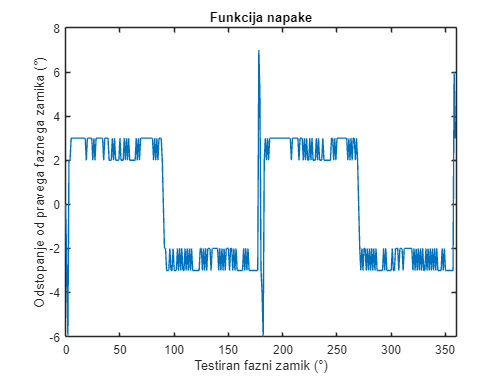


f2= figure(2);
errval = (phase-test_phase_deg) -360*((phase-test_phase_deg) > 180);
errval = errval + 360*(errval < -180);
plot(test_phase_deg, errval);
title("Funkcija napake");
xlabel("Testiran fazni zamik (°)");
ylabel("Odstopanje od pravega faznega zamika (°)");
xlim([0 360]);

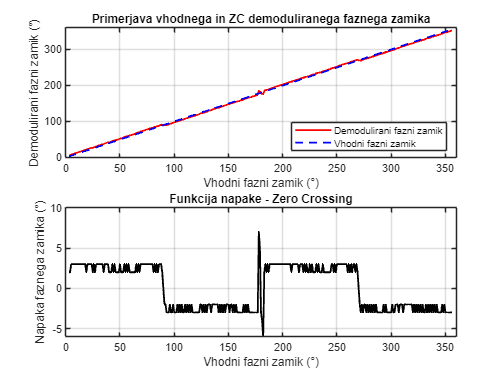



% Izris rezultatov
figure;
subplot(2, 1, 1);
cropf = 3;
plot(test_phase_deg(1+cropf:end-cropf), mod(phase(1+cropf:end-cropf), 360), 'r', 'LineWidth', 1.5);
hold on;
plot(test_phase_deg(1+cropf:end-cropf), test_phase_deg(1+cropf:end-cropf), 'b--', 'LineWidth', 1.5);
title('Primerjava vhodnega in ZC demoduliranega faznega zamika');
xlabel('Vhodni fazni zamik (°)');
ylabel('Demodulirani fazni zamik (°)');
legend('Demodulirani fazni zamik', 'Vhodni fazni zamik');
legend({'Demodulirani fazni zamik', 'Vhodni fazni zamik'}, 'Location', 'southeast');
ylim([0 360])
xlim([0 360])
grid on;

subplot(2, 1, 2);
plot(test_phase_deg(1+cropf:end-cropf), errval(1+cropf:end-cropf), 'k', 'LineWidth', 1.5);
title('Funkcija napake - Zero Crossing');
xlabel('Vhodni fazni zamik (°)');
ylabel('Napaka faznega zamika (°)');
xlim([0 360])
grid on;


% Izpis napak
fprintf('Največja napaka faze: %.2f stopinj\n', max( abs (errval(1+cropf:end-cropf)) ) );

Največja napaka faze: 7.00 stopinj


fprintf('Povprečna absolutna napaka faze: %.2f stopinj\n', mean(abs(errval(1+cropf:end-cropf))));

Povprečna absolutna napaka faze: 2.62 stopinj
